# S曲线规划

Reference: [https://zhuanlan.zhihu.com/p/652803608](https://zhuanlan.zhihu.com/p/652803608)

% 边界条件
q0 = 100; q1 = 120; 
v0 = 5; v1 = 0;
vmax = 0; amax = 10; jmax = 30;
sigma = sign(q1 - q0);
% 得到规划参数Ta, Tv, Td, Tj1, Tj2, q0, q1, v0, v1, vlim, amax, amin, alima, alimd, jmax, jmin
para = STrajectoryPara(q0, q1, v0, v1, vmax, amax, jmax)

para =     1.1052         0    1.6052    0.3333    0.3333  100.0000  120.0000    5.0000         0   12.7189   10.0000  -10.0000   10.0000  -10.0000   30.0000  -30.0000


i = 1; 
T = para(1) + para(2) + para(3)

T = 2.7104

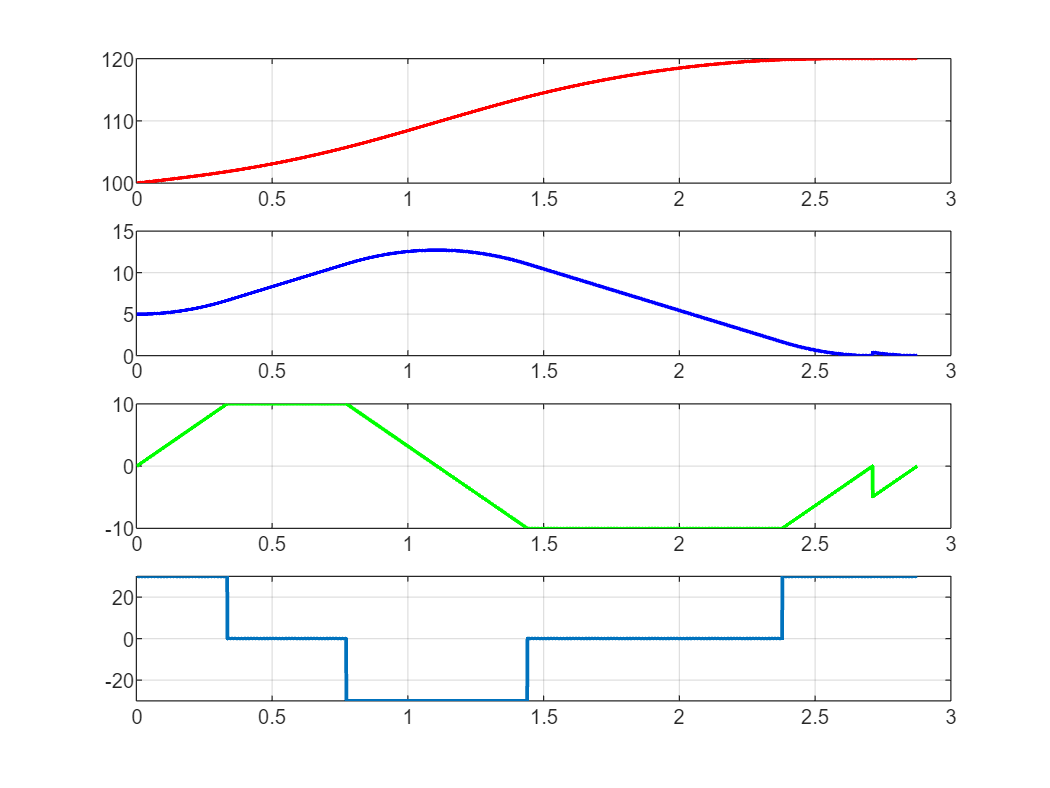

for t = 0: 0.001: T
   time(i) = 0.001*i;
   q(i) = S_position(t, para(1), para(2), para(3), para(4), para(5), para(6), para(7), para(8), para(9), para(10), para(11), para(12), para(13), para(14), para(15), para(16));
   qd(i) = S_velocity(t, para(1), para(2), para(3), para(4), para(5), para(6), para(7), para(8), para(9), para(10), para(11), para(12), para(13), para(14), para(15), para(16));
   qdd(i) = S_acceleration(t, para(1), para(2), para(3), para(4), para(5), para(6), para(7), para(8), para(9), para(10), para(11), para(12), para(13), para(14), para(15), para(16));
   qddd(i) = S_jerk(t, para(1), para(2), para(3), para(4), para(5), para(6), para(7), para(8), para(9), para(10), para(11), para(12), para(13), para(14), para(15), para(16));
   i = i + 1;
end
q = sigma*q;
qd = sigma*qd;
qdd = sigma*qdd;
qddd = sigma*qddd;
figure(1)
subplot(4, 1, 1)
plot(time, q, 'r', 'LineWidth', 1.5)
grid on
subplot(4, 1, 2)
plot(time, qd, 'b', 'LineWidth', 1.5)
grid on
subplot(4, 1, 3)
plot(time, qdd, 'g', 'LineWidth', 1.5)
grid on
subplot(4, 1, 4)
plot(time, qddd, 'LineWidth', 1.5)
grid on

## 单关节空间规划

S曲线参数计算（S型速度规划，又称七段式轨迹）

function para = STrajectoryPara(q0, q1, v0, v1, vmax, amax, jmax)
% 得到规划参数Ta, Tv, Td, Tj1, Tj2, q0, q1, v0, v1, vlim, amax, amin, alima, alimd, jmax, jmin
% 用户给定参数
% 边界条件q0 = 10, q1 = 0, v0 = -7, v1 = 0
% 约束条件vmax = 10, amax = 10, jamx = 30
% q0 = 0; q1 = 10; 
% v0 = 7.5; v1 = 0;
% vmax = 10; amax = 10; jmax = 30;
vmin = -vmax; amin = -amax; jmin = -jmax;


### 利用公式（3.31）（3.32）转化得到实际的q_0、q_1、v_max、a_max

sigma = sign(q1 - q0);  
q_0 = sigma*q0;
q_1 = sigma*q1;
v_0 = sigma*v0;
v_1 = sigma*v1;
v_max = ((sigma+1)/2)*vmax + ((sigma-1)/2)*vmin;
v_min = ((sigma+1)/2)*vmin + ((sigma-1)/2)*vmax;
a_max = ((sigma+1)/2)*amax + ((sigma-1)/2)*amin;
a_min = ((sigma+1)/2)*amin + ((sigma-1)/2)*amax;
j_max = ((sigma+1)/2)*jmax + ((sigma-1)/2)*jmin;
j_min = ((sigma+1)/2)*jmin + ((sigma-1)/2)*jmax;


### 判断是否达到最大速度

if ((v_max - v_0)*j_max < a_max^2) 
    Tj1 = sqrt((v_max - v_0) / j_max); % 达不到a_max
    Ta = 2*Tj1;
    a_lima = j_max * Tj1;
else
    Tj1 = a_max / j_max; % 能够达到a_max
    Ta = Tj1 + (v_max - v_0) / a_max;
    a_lima = a_max;
end
if ((v_max - v_1)*j_max < a_max^2)
    Tj2 = sqrt((v_max - v_1) / j_max); % 达不到a_min
    Td = 2*Tj2;
    a_limd =  -j_max * Tj2;
else
    Tj2 = a_max / j_max; % 能够达到a_min
    Td = Tj2 + (v_max - v_1) / a_max;
    a_limd = -a_max;
end
% 根据（3.25）计算匀速段时间
Tv = (q_1 - q_0)/v_max - (Ta/2)*(1 + v_0/v_max) - (Td/2)*(1 + v_1/v_max);


### 对Tv进行讨论

if (Tv > 0)
    % 达到最大速度v_max，即存在匀速阶段
    vlim = v_max;
    T = Ta + Tv + Td;
    para = [Ta, Tv, Td, Tj1, Tj2, q_0, q_1, v_0, v_1, vlim, a_max, a_min, a_lima, a_limd, j_max, j_min];
    return;
else
    % 达不到最大速度，即匀速阶段Tv=0
    % 假设最大加速度和最小加速度均能达到
    Tv = 0;
    Tj = a_max / j_max;
    Tj1 = Tj;
    Tj2 = Tj;
    delta = (a_max^4/j_max^2) + 2*(v_0^2 + v_1^2) + a_max*(4*(q_1 - q_0) - 2*(a_max/j_max)*(v_0 + v_1));
    Ta = ((power(a_max, 2)/j_max) - 2.0*v_0 + sqrt(delta)) / (2.0*a_max);
    Td = ((power(a_max, 2)/j_max) - 2.0*v_1 + sqrt(delta)) / (2.0*a_max);
    % 对Ta和Td进行讨论
    if (Ta < 0 || Td < 0)
        if (Ta < 0)
            % 没有加速段，只有减速段
            Ta = 0; Tj1 = 0;
            Td = 2*(q_1 - q_0) / (v_0 + v_1);
            Tj2 = (j_max*(q_1 - q_0) - sqrt(j_max*(j_max*power(q_1 - q_0, 2) + power(v_1 + v_0, 2)*(v_1 - v_0)))) / (j_max*(v_1 + v_0));
            a_lima = 0;
            a_limd = -j_max*Tj2;
            vlim = v0;
            para = [Ta, Tv, Td, Tj1, Tj2, q_0, q_1, v_0, v_1, vlim, a_max, a_min, a_lima, a_limd, j_max, j_min];
            return;
        elseif (Td < 0)
            % 没有减速段，只有加速段
            Td = 0; Tj2 = 0;
            Ta = 2*(q_1 - q_0) / (v_0 + v_1);
            Tj1 = (j_max*(q_1 - q_0) - sqrt(j_max*(j_max*power(q_1 - q_0, 2)) - power(v_1 + v_0, 2)*(v_1 - v_0))) / (j_max*(v_1 + v_0));
            a_lima = j_max*Tj1;
            a_limd = 0;
            vlim = v_0 + a_lima*(Ta - Tj1);
            para = [Ta, Tv, Td, Tj1, Tj2, q_0, q_1, v_0, v_1, vlim, a_max, a_min, a_lima, a_limd, j_max, j_min];
            return;
        end
    elseif (Ta >= 2*Tj && Td >= 2*Tj)
        % 加速段和减速段都能达到最大加速度
        a_lima = a_max;
        a_limd = -a_max;
        vlim = v0 + a_lima*(Ta - Tj);
        para = [Ta, Tv, Td, Tj1, Tj2, q_0, q_1, v_0, v_1, vlim, a_max, a_min, a_lima, a_limd, j_max, j_min];
        return;
    else
        % 加速和减速阶段至少有一段不能达到最大加速度
        lambda = 0.99; % 系统取0<lambda<1
        while (Ta < 2*Tj || Td < 2*Tj)
            % 循环
            a_max = lambda*a_max;
            Tv = 0;
            Tj = a_max / j_max;
            Tj1 = Tj;
            Tj2 = Tj;
            delta = (a_max^4/j_max^2) + 2*(v_0^2 + v_1^2) + a_max*(4*(q_1 - q_0) - 2*(a_max/j_max)*(v_0 + v_1));
            Ta = ((power(a_max, 2)/j_max) - 2.0*v_0 + sqrt(delta)) / (2.0*a_max);
            Td = ((power(a_max, 2)/j_max) - 2.0*v_1 + sqrt(delta)) / (2.0*a_max);
            if (Ta < 0 || Td < 0)
                if (Ta < 0)
                    % 没有加速段，只有减速段
                    Ta = 0; Tj1 = 0;
                    Td = 2*(q_1 - q_0) / (v_0 + v_1);
                    Tj2 = (j_max*(q_1 - q_0) - sqrt(j_max*(j_max*power(q_1 - q_0, 2) + power(v_1 + v_0, 2)*(v_1 - v_0)))) / (j_max*(v_1 + v_0));
                    a_lima = 0;
                    a_limd = -j_max*Tj2;
                    vlim = v0;
                    para = [Ta, Tv, Td, Tj1, Tj2, q_0, q_1, v_0, v_1, vlim, a_max, a_min, a_lima, a_limd, j_max, j_min];
                    return;
                elseif (Td < 0)
                    % 没有减速段，只有加速段
                    Td = 0; Tj2 = 0;
                    Ta = 2*(q_1 - q_0) / (v_0 + v_1);
                    Tj1 = (j_max*(q_1 - q_0) - sqrt(j_max*(j_max*power(q_1 - q_0, 2)) - power(v_1 + v_0, 2)*(v_1 - v_0))) / (j_max*(v_1 + v_0));
                    a_lima = j_max*Tj1;
                    a_limd = 0;
                    vlim = v_0 + a_lima*(Ta - Tj1);
                    para = [Ta, Tv, Td, Tj1, Tj2, q_0, q_1, v_0, v_1, vlim, a_max, a_min, a_lima, a_limd, j_max, j_min];
                    return;
                end
            elseif (Ta >= 2*Tj && Td >= 2*Tj)
                % 加速段和减速段都能达到最大加速度
                a_lima = a_max;
                a_limd = -a_max;
                vlim = v0 + a_lima*(Ta - Tj);
                para = [Ta, Tv, Td, Tj1, Tj2, q_0, q_1, v_0, v_1, vlim, a_max, a_min, a_lima, a_limd, j_max, j_min];
                return;
            end
        end
    end
end
end

## 计算位移

function q = S_position(t, Ta, Tv, Td, Tj1, Tj2, q0, q1, v0, v1, vlim, amax, amin, alima, alimd, jmax, jmin)
T = Ta + Tv + Td;
% 加速段
if (t >= 0 && t < Tj1)
    q = q0 + v0*t + jmax*t^3/6;
elseif (t >= Tj1 && t < Ta - Tj1)
    q = q0 + v0*t +(alima/6)*(3*t^2 - 3*Tj1*t + Tj1^2);
elseif (t >= Ta - Tj1 && t < Ta)
    q = q0 + (vlim + v0)*(Ta/2) - vlim*(Ta - t) - jmin*((Ta - t)^3/6);
% 匀速段
elseif (t >= Ta && t < Ta + Tv)
    q = q0 + (vlim + v0)*(Ta/2) + vlim*(t - Ta);
% 减速段
elseif (t >= Ta + Tv && t < T - Td + Tj2)
    q = q1 - (vlim + v1)*(Td/2) + vlim*(t - T + Td) - jmax*(power(t - T + Td, 3)/6);
elseif (t >= T - Td + Tj2 && t < T - Tj2)
    q = q1 - (vlim + v1)*(Td/2) + vlim*(t - T + Td) + (alimd/6)*(3*power(t - T + Td, 2) - 3*Tj2*(t - T + Td) + Tj2^2);
elseif (t >= T - Tj2 && t <= T)
    q = q1 - v1*(T - t) - jmax*(power(T - t, 3)/6);
end
end

## 计算速度

function qd = S_velocity(t, Ta, Tv, Td, Tj1, Tj2, q0, q1, v0, v1, vlim, amax, amin, alima, alimd, jmax, jmin)
T = Ta + Tv + Td;
if (t >= 0 && t < Tj1)
    qd = v0 + jmax*(t^2/2);
elseif (t >= Tj1 && t < Ta - Tj1)
    qd = v0 + alima*(t - Tj1/2);
elseif (t >= Ta - Tj1 && t < Ta)
    qd = vlim + jmin*(power(Ta - t, 2)/2);
% 匀速段
elseif (t >= Ta && t < Ta + Tv)
    qd = vlim;
% 减速段
elseif (t >= Ta + Tv && t < T - Td + Tj2)
    qd = vlim - jmax*(power(t - T + Td, 2)/2);
elseif (t >= T - Td + Tj2 && t < T - Tj2)
    qd = vlim + alimd*(t - T + Td - Tj2/2);
elseif (t >= T - Tj2 && t <= T)
    qd = v1 + jmax*(power(t - T, 2)/2);
end
end

## 计算加速度

function qdd = S_acceleration(t, Ta, Tv, Td, Tj1, Tj2, q0, q1, v0, v1, vlim, amax, amin, alima, alimd, jmax, jmin)
T = Ta + Tv + Td;
if (t >= 0 && t < Tj1)
    qdd = jmax*t;
elseif (t >= Tj1 && t < Ta - Tj1)
    qdd = alima;
elseif (t >= Ta - Tj1 && t < Ta)
    qdd = -jmin*(Ta - t);
% 匀速段
elseif (t >= Ta && t < Ta + Tv)
    qdd = 0;
% 减速段
elseif (t >= Ta + Tv && t < T - Td + Tj2)
    qdd = -jmax*(t - T + Td);
elseif (t >= T - Td + Tj2 && t < T - Tj2)
    qdd = alimd;
elseif (t >= T - Tj2 && t <= T)
    qdd = -jmax*(T - t);
end
end

## 计算加加速度

function qddd = S_jerk(t, Ta, Tv, Td, Tj1, Tj2, q0, q1, v0, v1, vlim, amax, amin, alima, alimd, jmax, jmin)
T = Ta + Tv + Td;
if (t >= 0 && t < Tj1)
    qddd = jmax;
elseif (t >= Tj1 && t < Ta - Tj1)
    qddd = 0;
elseif (t >= Ta - Tj1 && t < Ta)
    qddd = jmin;
% 匀速段
elseif (t >= Ta && t < Ta + Tv)
    qddd = 0;
% 减速段
elseif (t >= Ta + Tv && t < T - Td + Tj2)
    qddd = -jmax;
elseif (t >= T - Td + Tj2 && t < T - Tj2)
    qddd = 0;
elseif (t >= T - Tj2 && t <= T)
    qddd = jmax;
end
end